## **SoRoSim Toolbox**

**(Run section by section)**

This is an introductory example for new users. A simple example of a fixed-free beam under gravity is explained here. Some features of the GUI and output are not captured in this live script. 

Make sure that you are inside the toolbox main folder to run this live script. Run the startup file if it is not done automatically

startup

Welcome to SoRoSim Toolbox
Type LinkName=SorosimLink to create the links (joint and body)
Type LinkageName=SorosimLinkage(LinkName1,LinkName2,...,LinkNameN) to create linkages by combining links
For static equilibrium problem type [q,u]=LinkageName.statics
For dynamics problem type [t,qqd] = LinkageName.dynamics


To avoid unwanted modification of toolbox folders, choose a different path:

selpath = uigetdir(path)
oldpath = cd(selpath)

### Creation of a link

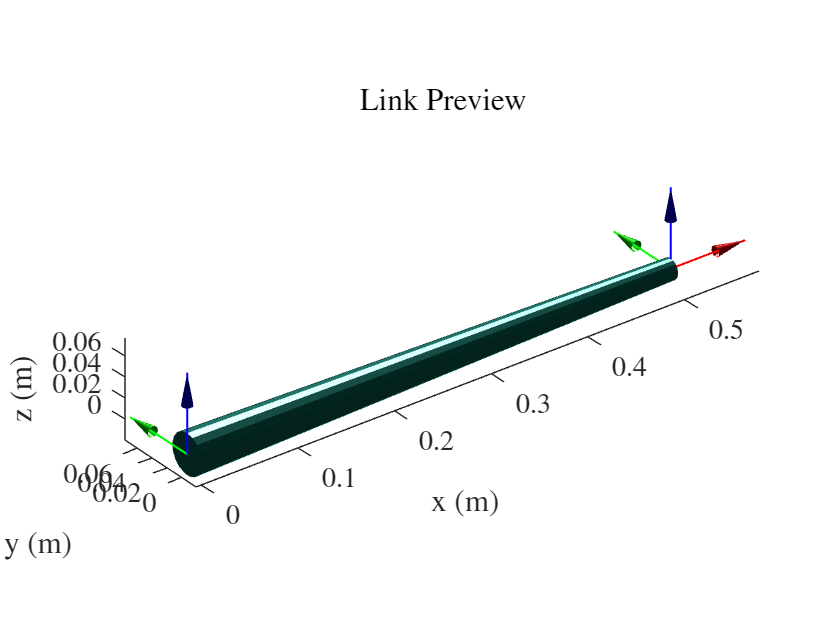

L1=SorosimLink;

The first dialog box that appears is:

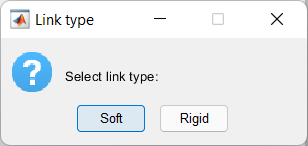

Choose Soft

The second dialog box is:

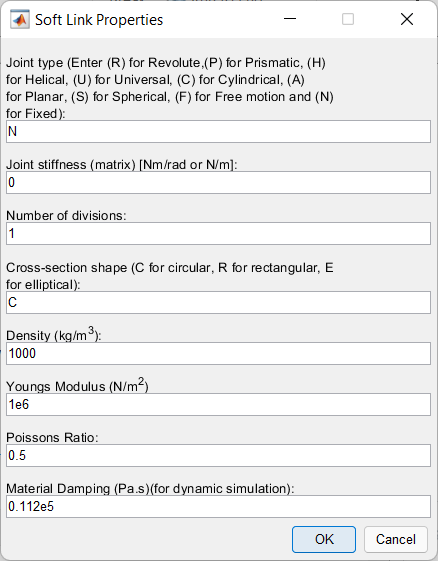

Keep the default values for this example.

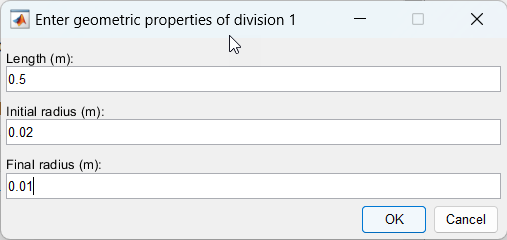

Change the length, initial, and final radius as shown. After this dialog box, the link creation is complete.

### Linkage Definition

We create a linkage by combining previously defined links. Here we use `L1` to create a SorosimLinkage `T1`.

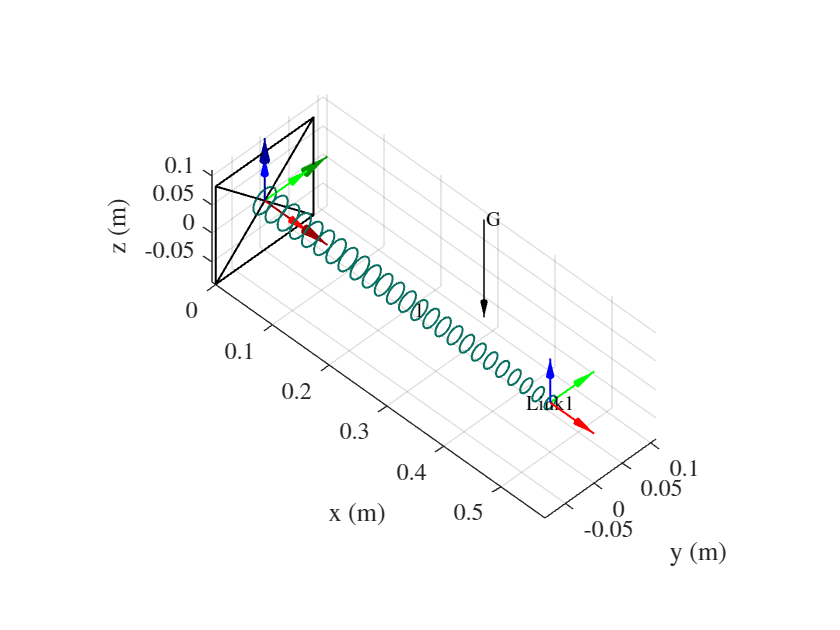

S1=SorosimLinkage(L1);

This will be followed by a series of dialog boxes as shown below:

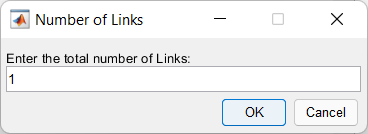

Here keep the default value of 1.

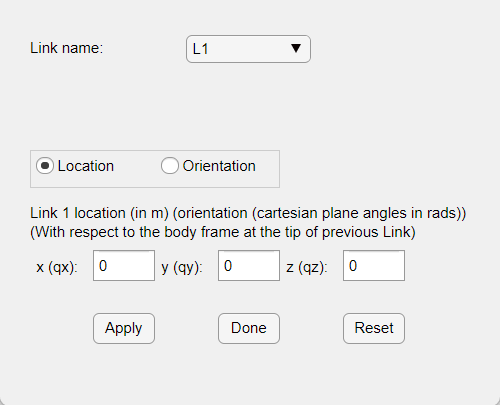

This dialog box is for the assembly of links. Choose Done. Images of the linkage assembly appear simultaneously with the dialog boxes.

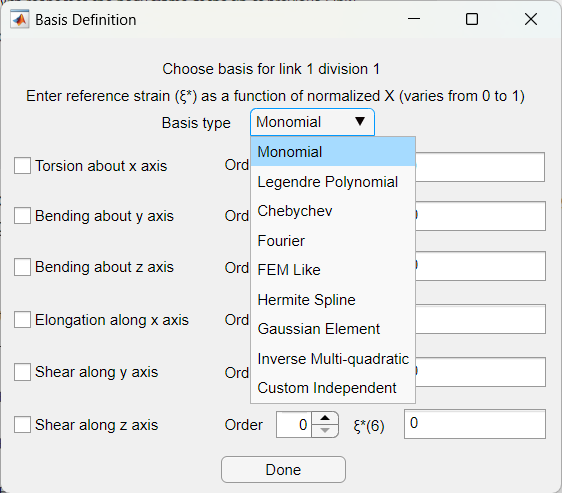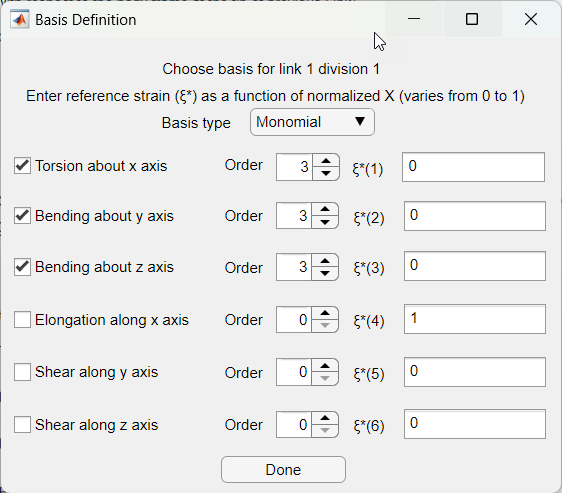

This is a dialog box to define the type of basis, degrees of freedom of a soft link division. Choose Monomial, the first 3 modes of deformation, and give an order of 3 for all of those ('Order' is the order of polynomial that is used to fit the respective strain value). $\xi =\Phi \mathit{\mathbf{q}}+\xi^*$, here we define $\Phi$ and $\xi^*$.

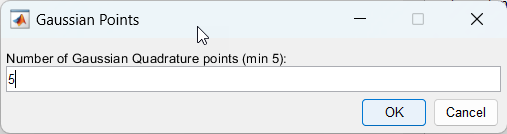

This dialog box is to specify the number of integration points. The default values should be good enough for typical problems. Feel free to increase.

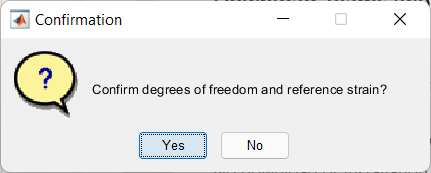

Choose Yes.

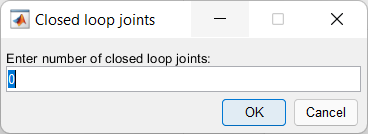

Choose the default value of 0 for this example. 

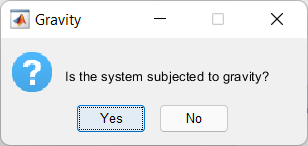

Choose Yes to add gravity load.

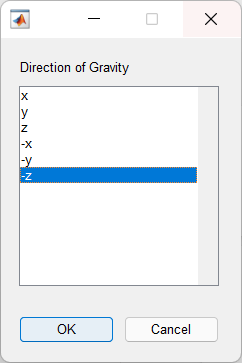

Choose the direction of gravity. Choose the default value.

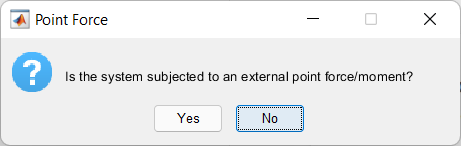

Choose No.

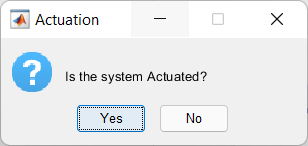

Choose No.

The linkage S`1` is created after this dialog box.

### Preview of the linkage created

The linkage can be viewed by typing,

S1.plotq0

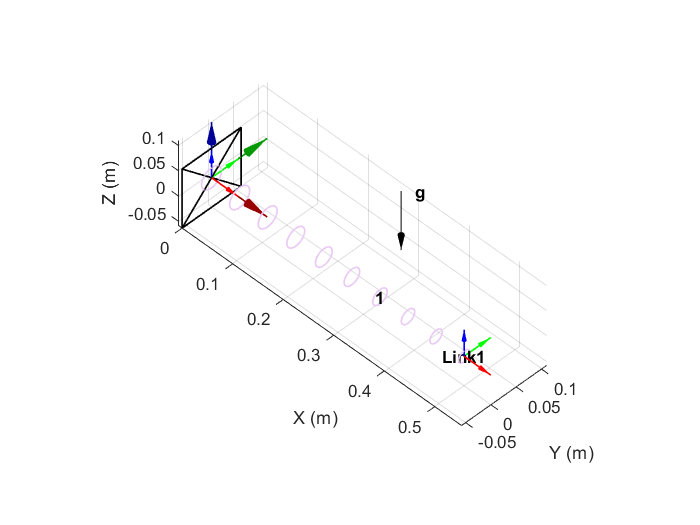

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1         4.48175e+10                        2.18e+10              1
     1          2         5.45211e+09              1         1.09e+10              1
     2          3         1.24188e+08            2.5         8.47e+08            2.5
     3          4             41086.5        1.29036         3.57e+07           6.25
     4          5         0.000488226      0.0102189         3.89e+03           6.25
     5          6          7.2096e-20    4.16451e-07         4.53e-05           6.25
     6          7         3.40122e-21    5.54552e-14         8.75e-06           6.25

Equation solved, solver stalled.

fsolve stopped because the relative 

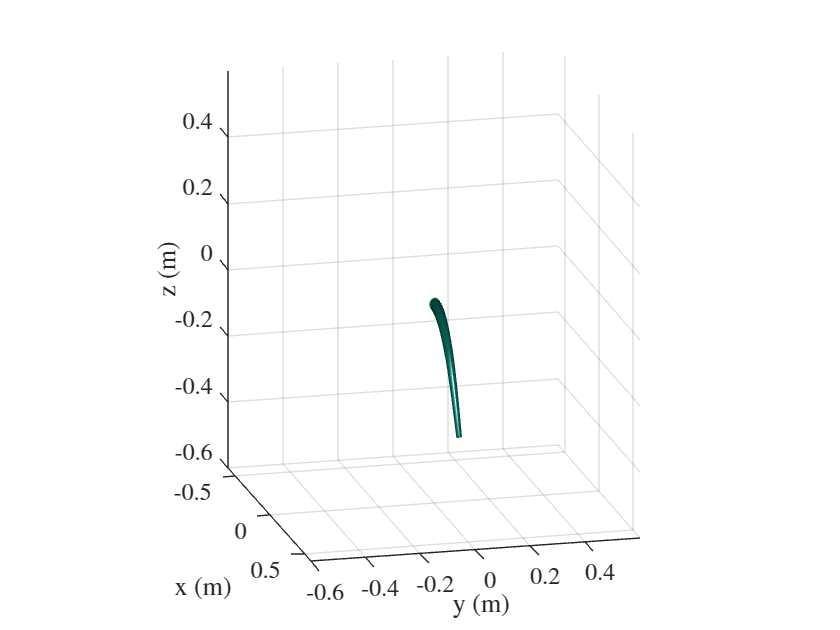

q=S1.statics;

A dialog box will pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

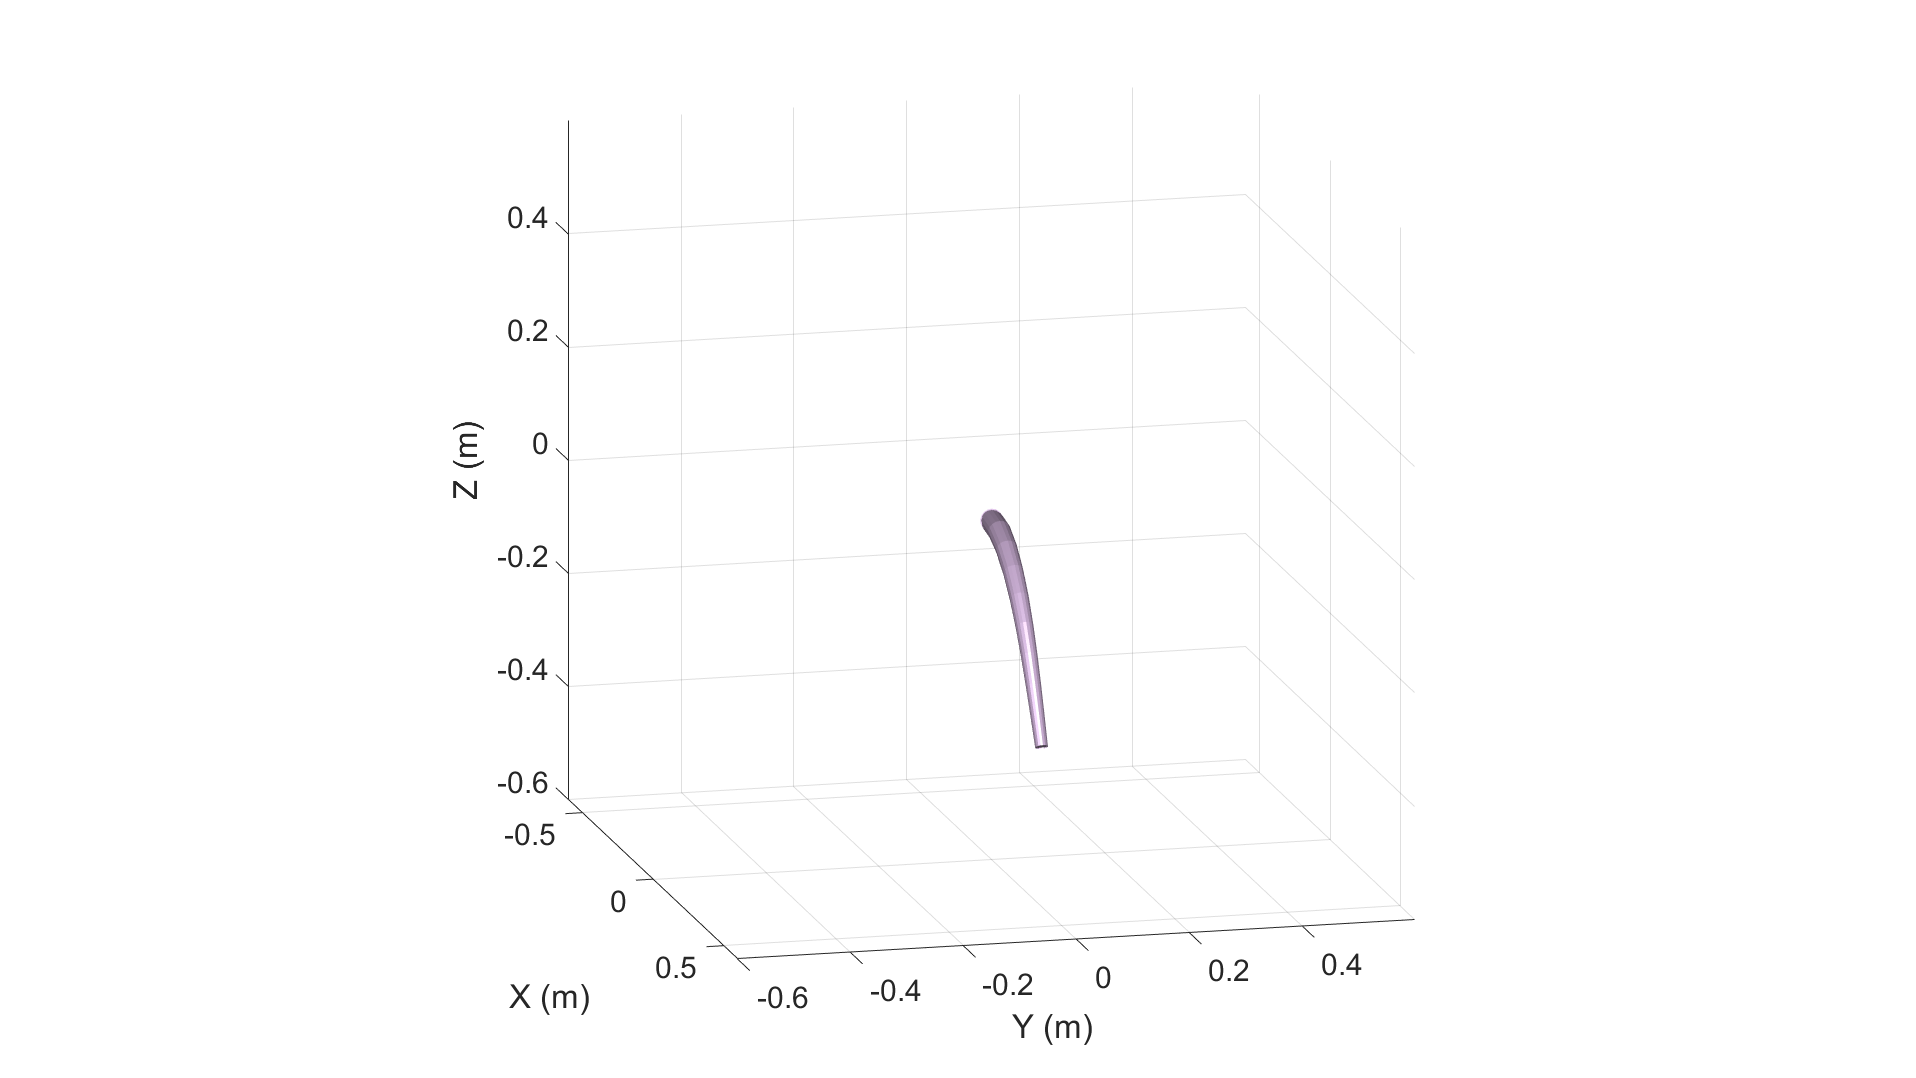

### **Dynamic simulation**

For dynamics problem, type:

Elapsed time is 0.312284 seconds.


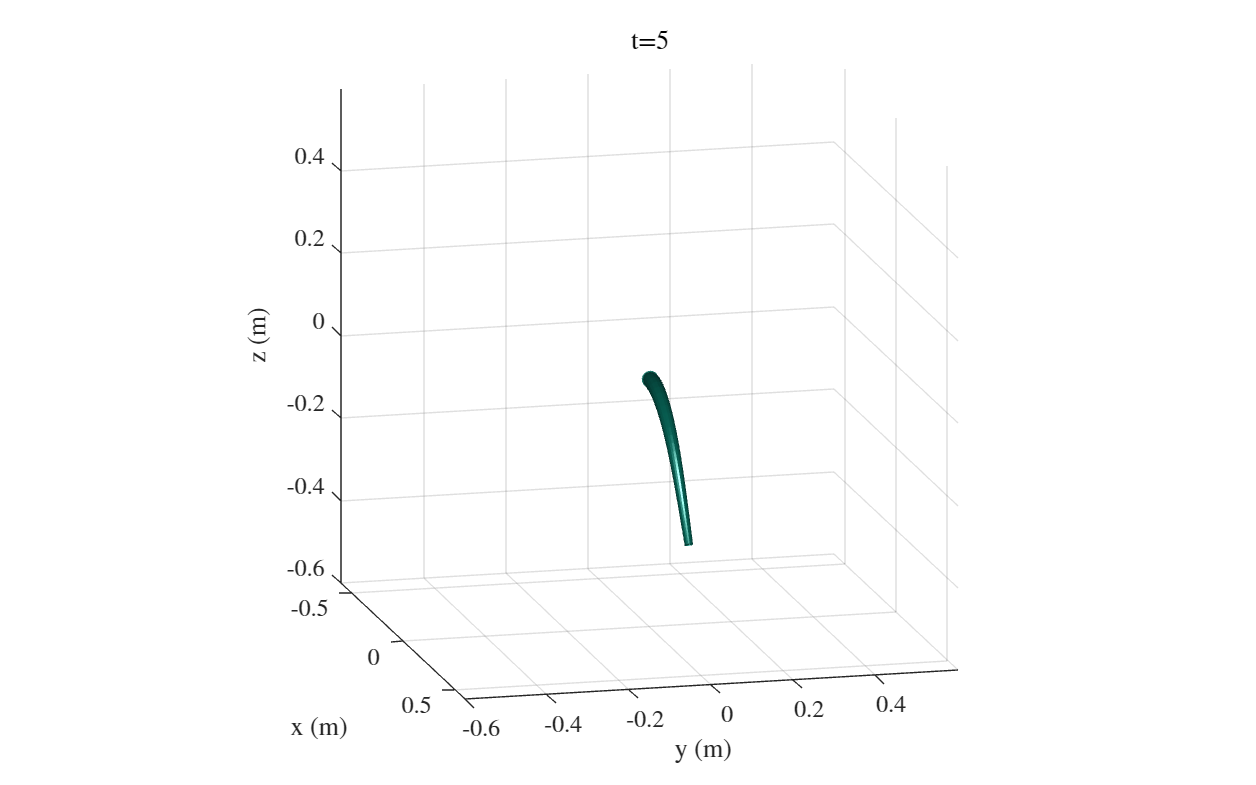

[t,qqd]=S1.dynamics;

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  Preview is not available in live script.

A video named `Dynamics.mp4` will be saved in the folder.

To return to the toolbox main folder:

cd(oldpath)

For more examples of pre-defined linkages check out the Example folder. It is preferable to run them in a separate folder. To copy the examples to the folder selected before:

copySoRoSimExamples(selpath)
cd(selpath)

Use matlab workspace to navigate into example folders in the new directory.

Enjoy the SoRoSim Toolbox!!!